# s_oeBloodFluorophoreTongueSrch 

The notes are in s_oeBloodFluorophoreLipSrch.mlx.

## Initialize

Different analyses are based on different wavebands.

ieInit;
wave = 500:600;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
[T,dataDir] = oeDatabaseCreate;

## Create fluorophore matrix and read database 

We create the base fluorophore emissions matrix.  It does not include blood (fluorophoresB).  Below, we sweep through different potential levels of blood optical density, checking how well the modified fluorophore matrix predicts the data samples.  Notice that the effective optical density of blood can depend on the wavelength of the excitation light.  Some lights will penetrate into the skin (substrate) more deeply than others, thus creating a longer path through the blood.

We tried many fluorophore files from the literature. These are described in in **s_oeFluorophoreEmissions.mlx**.  

Apart from FAD, all of the fluorophore emission spectra decline in the wave band from 500-600nm.  They exact emissions differ between labs, but the slopes are similar.

For the lip, there is no keratin, porphyrins, or chlorophyll.  We selected which to use in the s_oeBloodFluorophoreBasis.mlx script.

**Things we tried.**

- fluorophoreNames = {'collagen1','FAD_webfluor'}; -  Not enough dimensions. Fails to fit the data closely.

- fluorophoreNames = {'collagen1','elastin_webfluor','FAD_webfluor','NADH_webfluor'}; - Never chooses elastin

- fluorophoreNames = {'collagen1','FAD_webfluor','KeratinValdez'}; - Replaced NADH with Keratin.  Removed elastin. Too flat around 540, and a deep dive around 580.  General slope is OK.

- fluorophoreNames = {'collagen1','KeratinValdez','FADValdez'}; - Way off. Doesn't even get an OK fit of the blood.

- fluorophoreNames = {'CollagenWuQu','FADLin'}; - Way off, as above. Fails with blood

- fluorophoreNames = {'CollagenWuQu','FADValdez'}; - Way off as above.

- fluorophoreNames = {'CollagenWuQu','FAD_webfluor'}; - FIt is bad, but the blood is OK.

- fluorophoreNames = {'CollagenWuQu','elastin_webfluor','FADValdez'}; - Another blood miss.

- fluorophoreNames = {'collagen7','elastin_webfluor','FADValdez'}; - This collagen is goofy, and the fits are bad including the blood.

We should try a few more examples with Keratin.

**Our winners so far**

- fluorophoreNames = {'CollagenWuQu','NADH_webfluor','FADLin'}; - Best fit so far.  

- fluorophoreNames = {'collagen1','NADH_webfluor','FADLin'}; - Still good if we swap collagen1 for ColalgenWuQu.  That's a good thing.  

We should also try deoxygenated blood at some point, by adding in a collagen-deoxy column.

fluorophoreNamesB = {'collagen1','FADLin'};
[fluorophoresB,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## 405/415 nm excitation

subjects = {'Z','B','D','J'};

% Here is oxy
% https://omlc.org/spectra/hemoglobin/summary.html
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);
odError = zeros(numel(odLevels),numel(subjects));  
ods = zeros(numel(subjects),1);    
rmse = zeros(size(subjects));

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405,'e level',980);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415,'e level',910);
    tongueFiles = cat(1,files405,files415);

    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);    
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,tongueData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 1.00
OD across subjects for 405/415nm 1.00
OD across subjects for 405/415nm 1.00
OD across subjects for 405/415nm 1.00


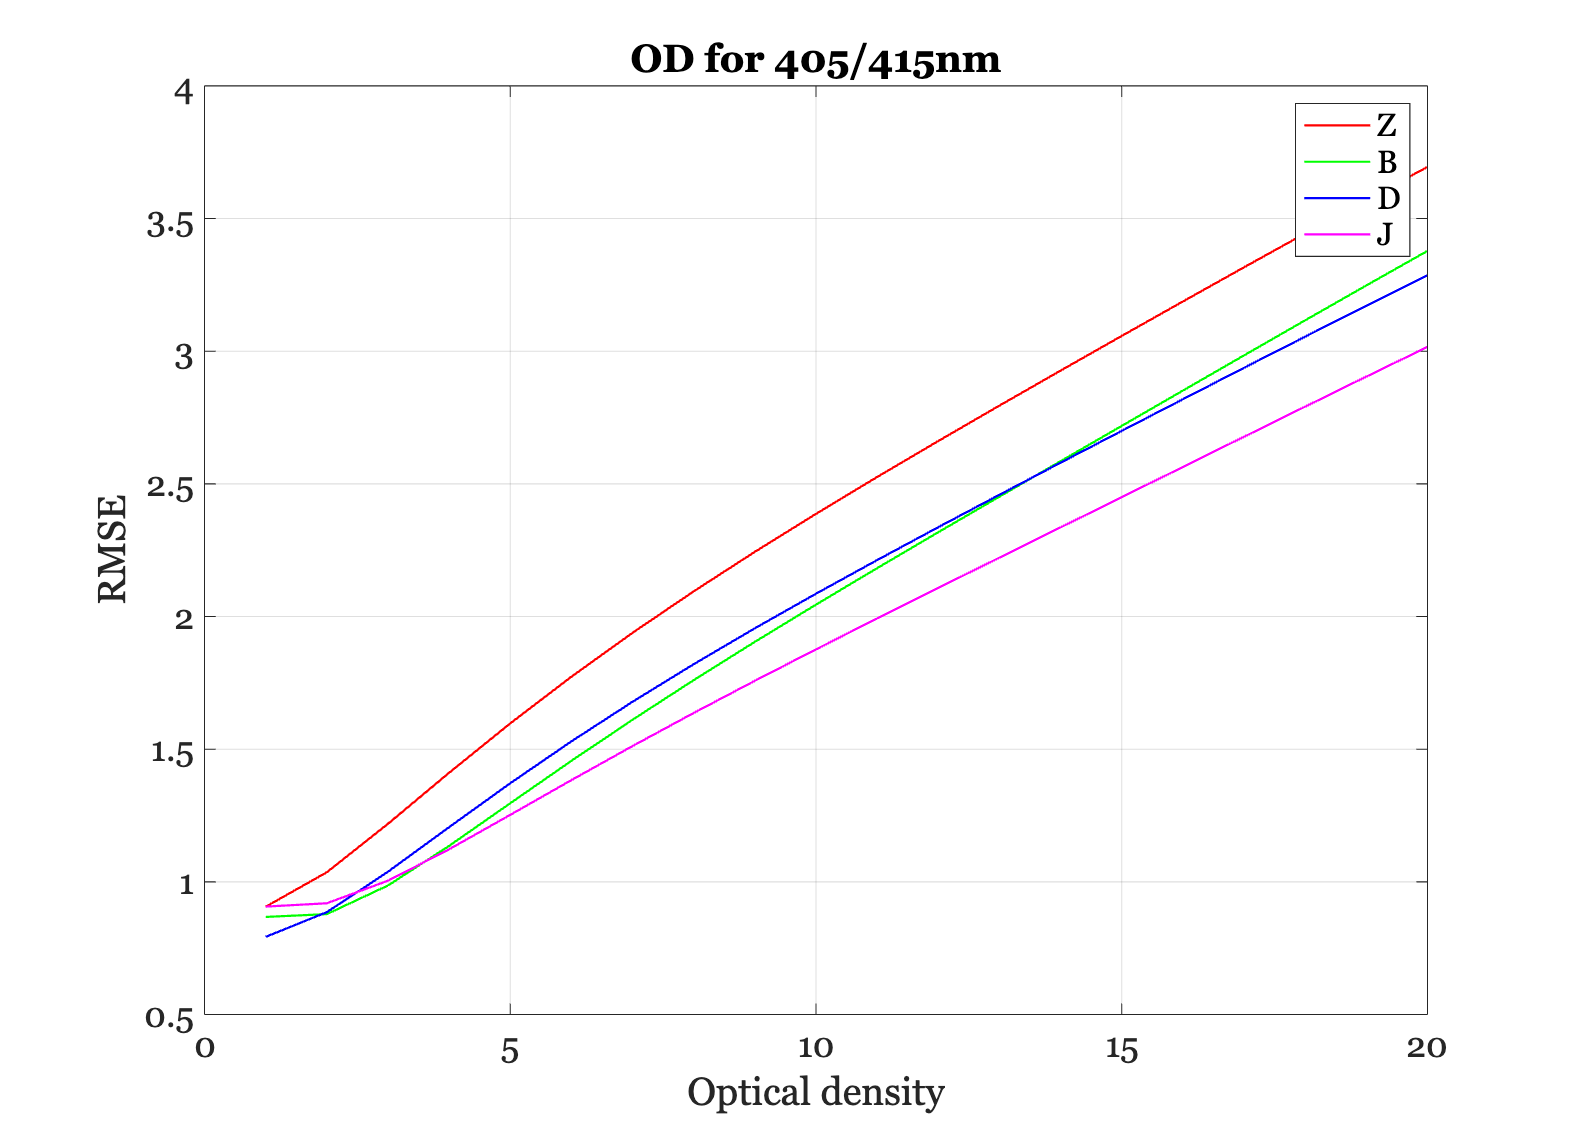


% These are the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 405/415nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## Apply the proper optical density and plot

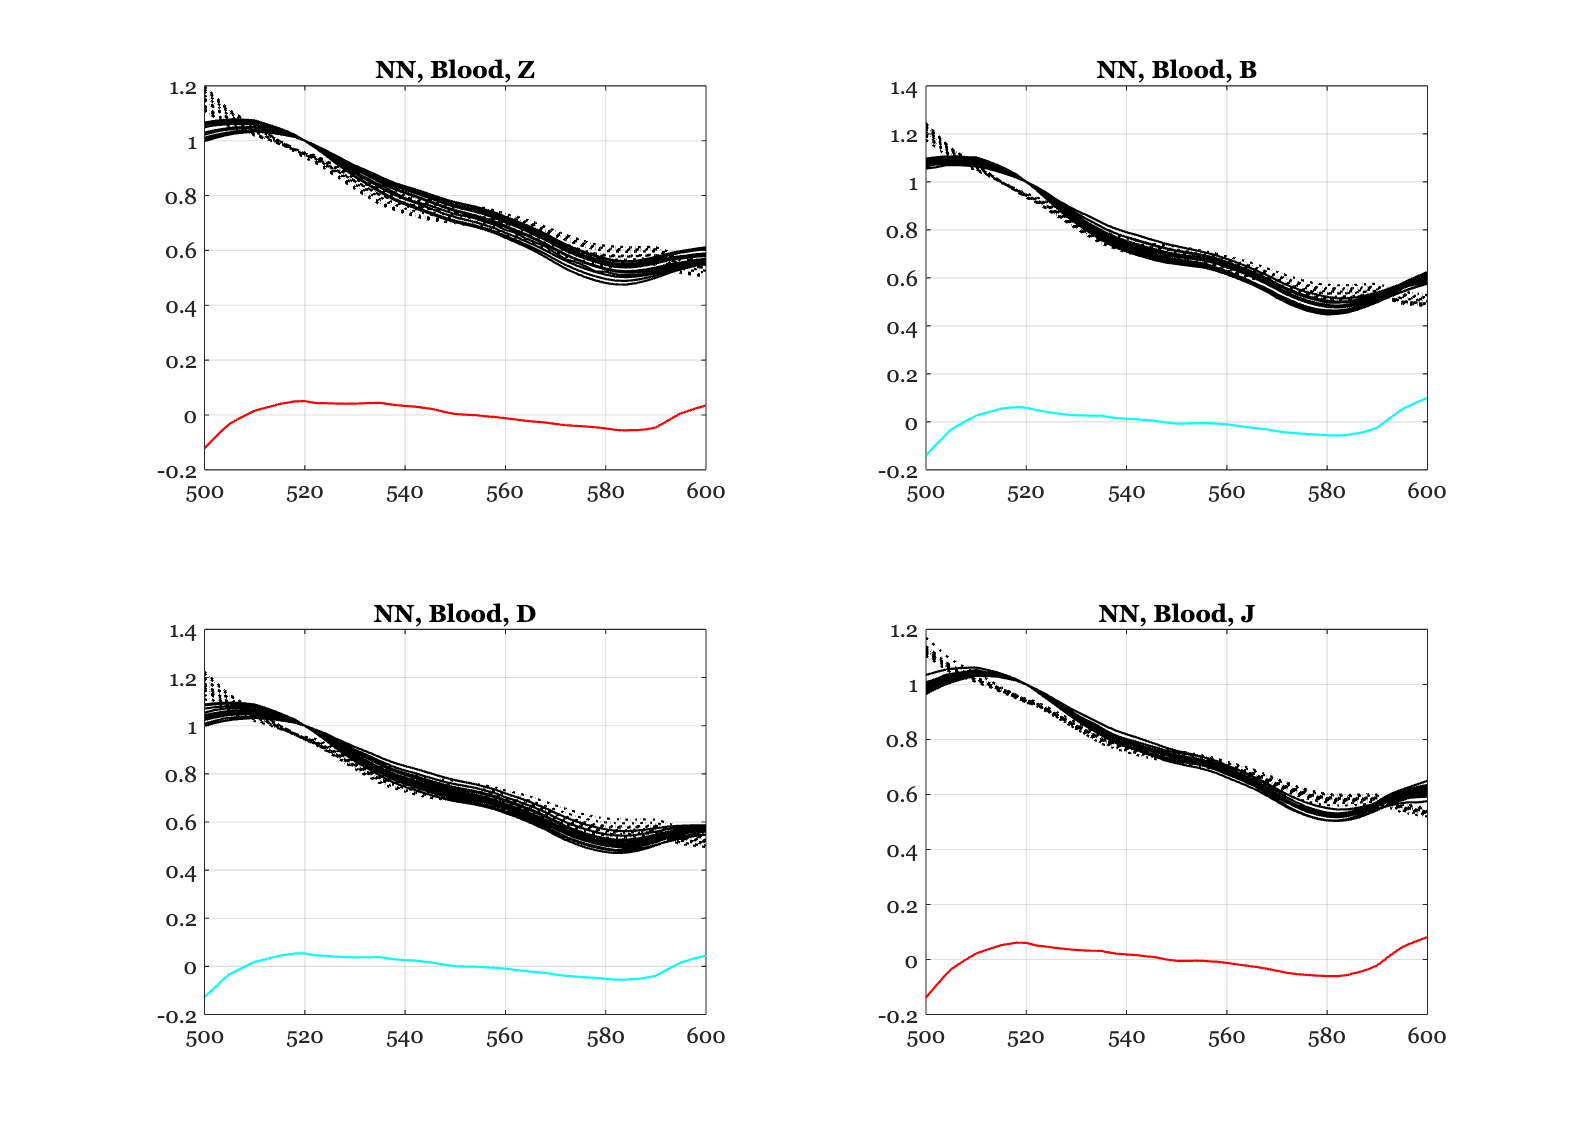

Subject Z
    8.9199    8.7504    8.5273    9.1164    7.6464    7.9808    7.6750    8.2924    7.8861    7.9357    7.8046    9.1012    8.3724    8.3184    8.3260
    0.3780    0.3938    0.4136    0.3584    0.4822    0.4511    0.4814    0.4253    0.4624    0.4555    0.4676    0.3519    0.4200    0.4228    0.4223
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Subject B
    9.4125    8.6855    8.9495    9.1410    9.6552    9.8637    9.8572    9.3434    9.5678    9.7864    9.7930    9.3123    9.0308    9.1452
    0.3365    0.3993    0.3759    0.3042    0.3108    0.2926    0.2941    0.3095    0.3175    0.2992    0.2992    0.3409    0.3678    0.3543
         0         0         0    1.0430         0         0         0    0.5788         0         0         0         0         0         0

Subject D
    9.3886    9.0757    9.5275    8.3633    8.3707    8.2923    8.7220    7.9836    8.4477  

ieFigure;
tiledlayout(2,2);

deoxyblood = medium('deoxy_molarExtinctionCoefficient.mat','wave',wave);
deoxyblood.opticalDensity = 5;

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);

    oxyblood.opticalDensity = ods(ii);
    [fluorophores, fluorophoreNames]  = oeApplyBlood(fluorophoresB,fluorophoreNamesB,...
        oxyblood, ...
        'deoxy',deoxyblood);
    wgtsNN = zeros(size(fluorophores,2),size(tongueData,2));

    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end
    residual = tongueData - fluorophores*wgtsNN;
    rmse(ii) = norm(residual(:),2);

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:', ...
        wave,mean(residual,2));
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end

disp(rmse); disp(fluorophoreNames);

    1.5265    1.6697    1.4846    1.7282

    {'collagen1-oxy'}    {'FADLin'}    {'collagen1-deoxy'}



## Create 450 nm blood optical density levels

odError = zeros(numel(odLevels),numel(subjects));

for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},...
        'substrate','tongue',...
        'e wave',450);
    tongueData = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNames,tongueData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 1.00
OD across subjects for 405/415nm 2.00
OD across subjects for 405/415nm 2.00
OD across subjects for 405/415nm 1.00


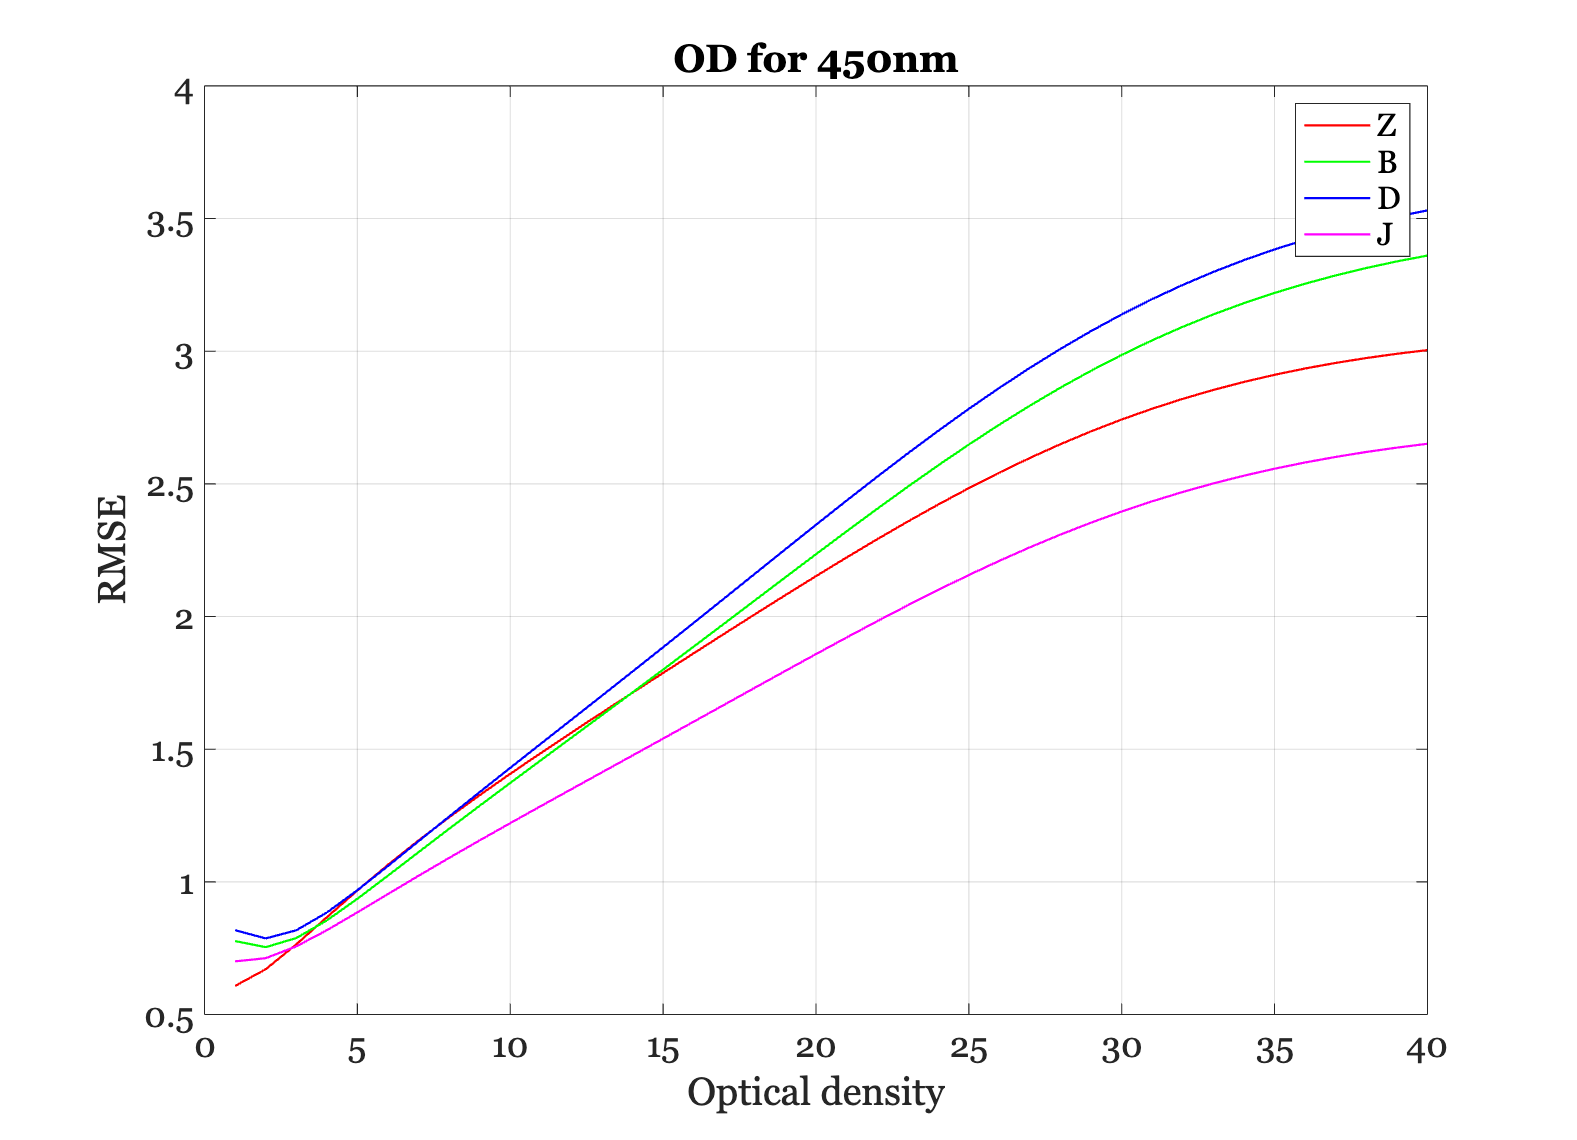



% These are the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 450nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## 450 nm excitation light

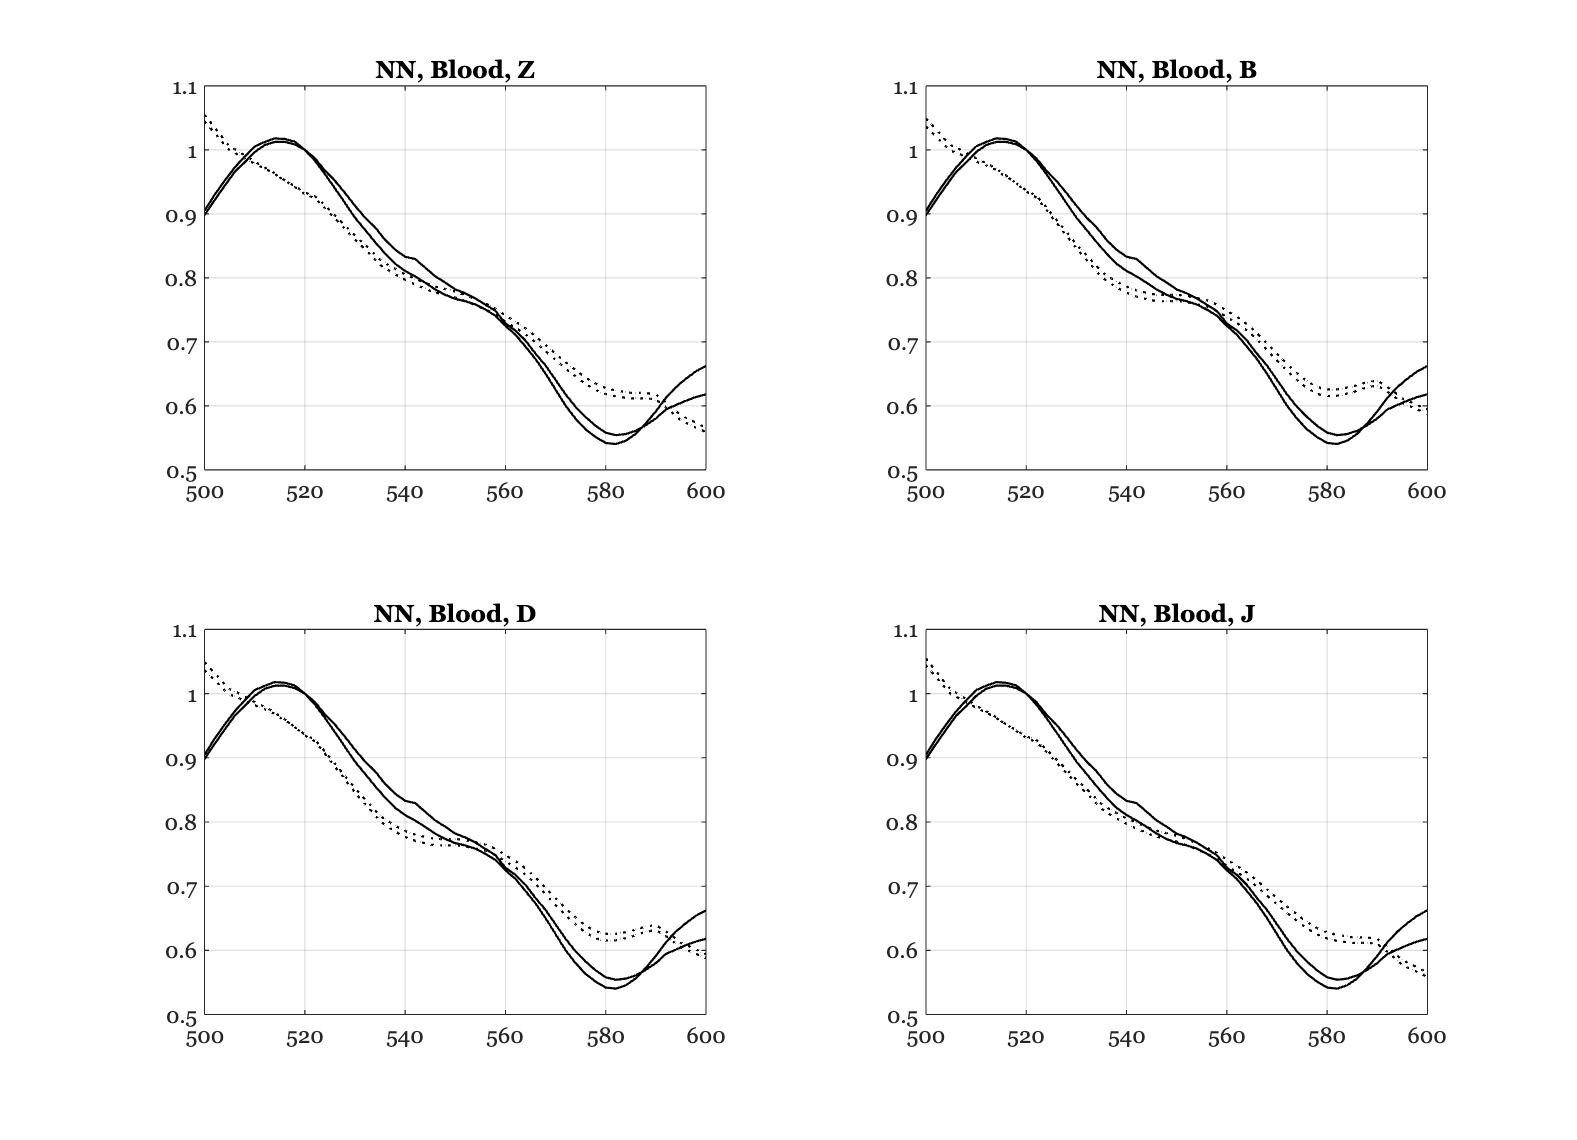

Subject Z
    7.0426    6.8643
    0.5019    0.5181

Subject B
    7.5132    7.2870
    0.5280    0.5452

Subject D
    7.5132    7.2870
    0.5280    0.5452

Subject J
    7.0426    6.8643
    0.5019    0.5181



ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)
    wgtsNN = zeros(size(fluorophores,2),size(tongueData,2));

    oxyblood.opticalDensity = ods(ii);
    fluorophores = oeApplyBlood(fluorophoresB,fluorophoreNames,oxyblood);
    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end